# Neural Network Classification

In this lab sheet we'll look at how to train and use a standard FeedForward network using built-in Matlab functions. Prerequisites:

- **You need to: (i) have a copy of the iris.csv dataset (available on Moodle) saved in the same directory as this live script, as well as the two .m files which you have downloaded from Moodle with this one; (ii) set Matlab's Current Folder to point at that directory**;

- This script assumes you have completed the Matlab Fundamentals materials.

## **Exploring models with artificial data**

**These first two tasks let you see how the activation (or transfer) functions work, and also how a simple neural network operates on 2D data.**

The transfer_functions code will plot a surface showing the relationship between variable inputs (the p1 and p2 values) and the output of a single neuron, for a given weight w, bias b and thechosen activation function. A range of options are avaiable, all but one commented out.

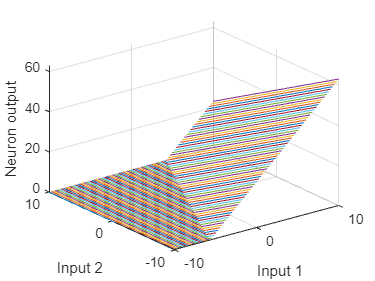

transfer_functions('poslin',[4 -2],3)

Vary the chosen function, and investigate the different effects. Marry the names here up with those mentioned in the lecture (unfortunately, they aren't the same); "help nntransfer" may also be useful, as is varying the w-values.

Now run multiPerceptron2 - it will build a network classifying the four classes A - D (each is a collection of quasi-random 2D points), report the training error and plot a graphshowing the areas in which the network report instances as being members of each class (since it does a softmax on the output, these are areas of maximal probability).

Correct classified samples: 100.0% samples


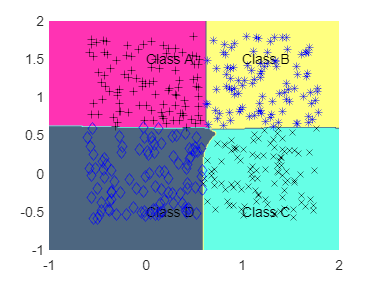

multiPerceptron2(0.5,1.2,[4 3],'tanh')

First vary the first two parameters to the function so that the data is not linearly separable. Then vary the number of nodes in the network (control this by the vector [4 3],) so as to reduce the error in the classifications. Note that while you may manage to reduce the training error, this is probably at the cost of some very oddly-shaped class boundaries. This isevidence of overfitting, as the boundaries are unlikley to be appropriate for other, new observations generated by the same processes as this training data.

Try varing the transfer functions, and also investigate the options avaiable in the "fitcnet" structure (try "help fitcnet" and also the help file on "Neural Network Object Properties"). Note that there is nothing to stop you having fewer or more layers that the two we have here, but the graphing functions will not operate if you change this. Incidently, all fitcnets have the extra final layer you can see in the GUI; this just allows a softMax (or similar) operation to be performed on the output of the nodes before a classification judement is made.

## Loading and preparing datasets

The following steps should all be familiar from the  k-NN lab. Refer back to it if you're not sure about any of the steps.

Read the iris dataset:

% read the iris dataset:
data = readcell('iris.csv');

Use it to create a testing dataset (25% of the data) and a training dataset (75% of the data):

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results

% write your code on the lines below

% SOLUTION:

data(1:1:1, :) = [];

shuffle = data(randperm(size(data, 1)), :);

% 60% training / 40% testing data
tempTest = round(0.4 * size(shuffle,1));

data_test = shuffle(1:1:tempTest, :);
data_train = shuffle(tempTest+1:1:end, :);


% identified visually, from output above:
label_index = 5;

% separate the examples and the labels for the testing dataset:
test_labels = categorical(data_test(:, label_index));
test_examples = cell2mat(data_test(:, 1:end~=label_index));

% separate the examples and the labels for the training dataset:
train_labels = categorical(data_train(:, label_index));
train_examples = cell2mat(data_train(:, 1:end~=label_index));


## Training a Neural Network classifier

Now we have our data organised, we can set up and train a Neural Network classifier by calling Matlab's  fitcnet`()` function.

The input arguments to fitcnet`() are`:

- `train_data` - our matrix of training examples

- `train_labels` - our categorical array of the associated class labels

- a string of options, defining the nature of the net

Note that we always have an additional layer with one node per output class. This performs a "softmax" activation function, comparing the values across the nodes and adjustting them so they are probabilities (i.e. they are all in the range [0,1] and sum to 1.0). 

The output from the` train()` function is:

- net - an object containing our trained model

After you run the following command, the properies of the resuling object, `net`, will be printed out. You will hopefully recognise at least some of them:

% create a neural network
net = fitcnet(train_examples,train_labels, ...
    'LayerSizes',[3 4],...
    'Activations','sigmoid',...
    'Verbose',1)

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.365528|    0.034745|    0.068942|    0.007028|
|           2|    0.356277|    0.009140|    0.300063|    0.006653|
|           3|    0.349817|    0.016659|    0.348241|    0.001471|
|           4|    0.337492|    0.046663|    1.707089|    0.001114|
|           5|    0.316430|    0.041977|    0.347985|    0.000459|
|           6|    0.258030|    0.135636|    2.969183|    0.000502|
|           7|    0.197899|    0.043461|    3.018427|    0.000459|
|           8|    0.170860|    0.023504|    2.402209|    0.000487|
|           9|    0.155762|    0.016773|    2.205473|    0.000455|
|          10|    0.148835|    0.012912|    1.723252|    0.000459|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [3 4]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [103×7 table]


  Properties, Methods


## Use your trained classifier for prediction

To predict class labels for our training examples based only on the features they contain we call Matlab's predict() function.

The input arguments to `net()` is:

- `net - the model we have just built`

- `train_data` - our matrix of testing examples

The output from `net()` is:

- `pred_train_labels` - an array of predicted class labels; one for each example (row) in the table `train_data.`

Exactly the same operations are done to `test_data`, generating `pred_train_labels. `In both cases, each observation gives a vector of three values (like the label vector generated from the original data).

% Get the prediced class memberships for the training and testing data
pred_train_labels = predict(net,train_examples);
pred_test_labels = predict(net,test_examples);

## Evaluating the classifier's performance

Let's evaluate the classifier's performance by generating confusion matrices for the training and testing data:

% output a confusion matrix:
[confusion_train,order_train] = confusionmat(train_labels, pred_train_labels)

confusion_train =     35     0     0
     0    27     1
     0     0    27


order_train = 3×1 categorical array
     setosa 
     versicolor 
     virginica 


[confusion_test,order_test] = confusionmat(test_labels, pred_test_labels)

confusion_test =     15     0     0
     0    22     0
     0     1    22


order_test = 3×1 categorical array
     setosa 
     versicolor 
     virginica 


And let's use the values in the confusion matrix to compute the overall classification accuracy:

% calculate the overall classification accuracies:
 perf_train = sum(diag(confusion_train)) / sum(confusion_train(1:1:end))

perf_train = 0.9889

 perf_test = sum(diag(confusion_test)) / sum(confusion_test(1:1:end))

perf_test = 0.9833

Check you can correctly interpret the values in the confusion matrix by completing the following questions. Use the sliders to select your answers:

% how many setosa irises are there in the testing data?
0

ans = 0

% how many of those setosa irises are correctly classified?
0

ans = 0

% how many versicolor irises are there in the testing data?
1

ans = 1

% how many of those versicolor irises are incorrectly classified as being virginica irises?
0

ans = 0

% how many virginica irises are there in the testing data?
1

ans = 1

% how many of those virginica irises are incorrectly classified as being versicolor irises?
1

ans = 1

## Extension task: adjusting hyperparameters

Have I got the right number of nodes in my Network? You can control this by the line in the code above which reads:

` %  'LayerSizes',[3 4],`

At the moment, it says that we want a net with two hidden layers of neurons, which have 3 and 4 neurons respectively.  You can add or subtract levels by altering the number of values in the [3 4] vector, or alter the number of neurons by changing the values in the vector.

Experiment with changing the number and size of the levels of neurons, until you maximize the classification rate on the testing data and minimize the size of the network. Put the experimention code here:

(**Hint**: the commented out line at the end is suggesting that you record the values of n1, n2 and a measure of performance on each row of the `results` array)



results = [];

for n1 = 2 : 5
    for n2 = 2 : 5
        net = fitcnet(train_examples,train_labels, ...
        'LayerSizes',[n1 n2],...
        'Activations','sigmoid',...
        'Verbose',1)
        
        pred_test_labels = predict(net,test_examples);
        
        [confusion_test,order_test] = confusionmat(test_labels, pred_test_labels);

        
        perf_test = sum(diag(confusion_test)) / sum(confusion_test(1:1:end)) * 100
        results(end+1,:) = [n1 n2 perf_test];

    
        
        % code and results go here

    end
end

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.371115|    0.030201|    0.058014|    0.000593|
|           2|    0.363968|    0.004581|    0.290137|    0.000462|
|           3|    0.363674|    0.004728|    0.047252|    0.000465|
|           4|    0.361692|    0.008125|    0.406037|    0.000438|
|           5|    0.356860|    0.024593|    1.190010|    0.000438|
|           6|    0.355016|    0.055234|    2.849222|    0.000520|
|           7|    0.342301|    0.038448|    0.189153|    0.000446|
|           8|    0.319329|    0.050594|    1.303100|    0.000433|
|           9|    0.280168|    0.045203|    4.205716|    0.000436|
|          10|    0.253131|    0.164436|    5.174690|    0.000570|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [2 2]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [28×7 table]


  Properties, Methods


perf_test = 61.6667

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.373080|    0.031075|    0.055465|    0.000645|
|           2|    0.364449|    0.004923|    0.393915|    0.000535|
|           3|    0.364150|    0.001248|    0.060104|    0.000532|
|           4|    0.364079|    0.001060|    0.024618|    0.000502|
|           5|    0.363820|    0.001671|    0.131498|    0.000502|
|           6|    0.359588|    0.035799|    2.003038|    0.001937|
|           7|    0.359207|    0.044486|    0.278250|    0.001950|
|           8|    0.266267|    0.034372|    4.838975|    0.001279|
|           9|    0.220664|    0.163336|    8.211948|    0.000874|
|          10|    0.219706|    0.208571|   14.494520|    0.000501|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [2 3]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [50×7 table]


  Properties, Methods


perf_test = 61.6667

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.392959|    0.057066|    0.147571|    0.001213|
|           2|    0.364989|    0.012830|    0.575068|    0.000623|
|           3|    0.363814|    0.002347|    0.104731|    0.000547|
|           4|    0.363726|    0.002353|    0.019535|    0.000558|
|           5|    0.363000|    0.006791|    0.214619|    0.000509|
|           6|    0.361328|    0.021110|    0.624985|    0.000540|
|           7|    0.357290|    0.060806|    1.539101|    0.000517|
|           8|    0.353238|    0.080338|    1.388825|    0.001239|
|           9|    0.347131|    0.077816|    1.892426|    0.000512|
|          10|    0.315687|    0.070518|    0.696795|    0.000506|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [2 4]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [42×7 table]


  Properties, Methods


perf_test = 96.6667

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.396356|    0.074024|    0.189953|    0.000678|
|           2|    0.360275|    0.005074|    0.510891|    0.000532|
|           3|    0.359297|    0.005815|    0.073600|    0.000516|
|           4|    0.344465|    0.051542|    1.516026|    0.001236|
|           5|    0.339628|    0.060476|    0.548401|    0.000891|
|           6|    0.296030|    0.049508|    0.721113|    0.000517|
|           7|    0.253934|    0.086378|    5.849400|    0.000737|
|           8|    0.158293|    0.064825|    1.354675|    0.000603|
|           9|    0.146449|    0.033868|    0.209138|    0.000544|
|          10|    0.139088|    0.006246|    0.747101|    0.000531|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [2 5]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [41×7 table]


  Properties, Methods


perf_test = 98.3333

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.369705|    0.039913|    0.063644|    0.000492|
|           2|    0.353009|    0.017009|    0.633082|    0.000441|
|           3|    0.321461|    0.027742|    1.310146|    0.001318|
|           4|    0.286155|    0.090483|    5.839687|    0.001013|
|           5|    0.221189|    0.062849|    1.986615|    0.000441|
|           6|    0.184327|    0.048586|    3.191493|    0.000445|
|           7|    0.156767|    0.014098|    3.567948|    0.000447|
|           8|    0.149914|    0.025421|    2.116653|    0.000479|
|           9|    0.146097|    0.017897|    8.249677|    0.000442|
|          10|    0.143314|    0.005863|    0.390491|    0.000442|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [3 2]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [160×7 table]


  Properties, Methods


perf_test = 91.6667

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.371641|    0.017870|    0.045246|    0.000556|
|           2|    0.365143|    0.004065|    0.308324|    0.000490|
|           3|    0.364249|    0.003348|    0.117428|    0.000456|
|           4|    0.362694|    0.008272|    0.366176|    0.000516|
|           5|    0.358518|    0.013455|    0.683947|    0.000602|
|           6|    0.357027|    0.022006|    0.426807|    0.000449|
|           7|    0.345966|    0.022840|    0.451079|    0.000446|
|           8|    0.324311|    0.071806|    1.711179|    0.000442|
|           9|    0.285751|    0.077766|    3.125645|    0.000474|
|          10|    0.217111|    0.051744|    1.823014|    0.000460|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [3 3]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [182×7 table]


  Properties, Methods


perf_test = 95

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.407673|    0.087071|    0.211526|    0.000500|
|           2|    0.358325|    0.006258|    0.627104|    0.000467|
|           3|    0.357206|    0.006921|    0.077436|    0.000468|
|           4|    0.352882|    0.021737|    0.505146|    0.000465|
|           5|    0.297164|    0.066914|    3.021721|    0.001447|
|           6|    0.282201|    0.091569|    1.966054|    0.002664|
|           7|    0.278492|    0.155878|    1.060829|    0.000485|
|           8|    0.249369|    0.070004|    0.204234|    0.000492|
|           9|    0.195678|    0.045332|    1.303333|    0.000525|
|          10|    0.168420|    0.024184|    2.291334|    0.000505|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [3 4]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [131×7 table]


  Properties, Methods


perf_test = 91.6667

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.367689|    0.021932|    0.052393|    0.000533|
|           2|    0.363551|    0.004617|    0.194033|    0.000546|
|           3|    0.363045|    0.004480|    0.057348|    0.000523|
|           4|    0.358402|    0.019897|    0.594226|    0.000813|
|           5|    0.352776|    0.064451|    1.062205|    0.001267|
|           6|    0.324221|    0.027722|    1.286821|    0.001210|
|           7|    0.312987|    0.167168|    2.173447|    0.000488|
|           8|    0.172006|    0.042037|    7.429098|    0.001238|
|           9|    0.141667|    0.007779|   12.597435|    0.000516|
|          10|    0.141200|    0.006325|    0.196604|    0.001382|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [3 5]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [132×7 table]


  Properties, Methods


perf_test = 90

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.402074|    0.069439|    0.137252|    0.000453|
|           2|    0.362341|    0.018248|    0.861196|    0.000470|
|           3|    0.358441|    0.006873|    0.184972|    0.000438|
|           4|    0.356392|    0.007788|    0.135893|    0.000432|
|           5|    0.348402|    0.047645|    1.503245|    0.000445|
|           6|    0.334660|    0.033875|    0.191312|    0.000518|
|           7|    0.272650|    0.022377|    2.901772|    0.000582|
|           8|    0.194030|    0.064633|    9.234229|    0.000608|
|           9|    0.172406|    0.031335|    2.510934|    0.000672|
|          10|    0.157760|    0.012187|    2.064718|    0.000459|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [4 2]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [47×7 table]


  Properties, Methods


perf_test = 60

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.377588|    0.045145|    0.087941|    0.000705|
|           2|    0.363448|    0.006262|    0.439192|    0.000627|
|           3|    0.362992|    0.003567|    0.062838|    0.000456|
|           4|    0.359457|    0.014056|    0.573783|    0.001707|
|           5|    0.358182|    0.015509|    0.269602|    0.000625|
|           6|    0.344972|    0.033138|    0.780125|    0.000441|
|           7|    0.335126|    0.054365|    1.234807|    0.001765|
|           8|    0.323437|    0.061503|    0.647325|    0.000461|
|           9|    0.260747|    0.236261|    7.246419|    0.000439|
|          10|    0.176899|    0.050990|    0.535644|    0.000467|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [4 3]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [49×7 table]


  Properties, Methods


perf_test = 95

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.403921|    0.070418|    0.168401|    0.000509|
|           2|    0.366630|    0.024528|    0.780173|    0.000516|
|           3|    0.361557|    0.005819|    0.218305|    0.000440|
|           4|    0.360271|    0.006774|    0.104979|    0.000734|
|           5|    0.353091|    0.026845|    1.205659|    0.000738|
|           6|    0.175424|    0.022776|    6.772668|    0.001548|
|           7|    0.153375|    0.037036|   30.488882|    0.000445|
|           8|    0.149019|    0.027702|    3.651794|    0.000982|
|           9|    0.140142|    0.011292|    1.762911|    0.000474|
|          10|    0.139464|    0.006716|    0.500842|    0.000554|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [4 4]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [55×7 table]


  Properties, Methods


perf_test = 100

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.388507|    0.050454|    0.156502|    0.000485|
|           2|    0.363965|    0.015246|    0.520028|    0.000663|
|           3|    0.362368|    0.005087|    0.110165|    0.000546|
|           4|    0.359150|    0.004795|    0.315100|    0.001921|
|           5|    0.354703|    0.009782|    1.022121|    0.000535|
|           6|    0.351216|    0.059052|    3.343623|    0.001469|
|           7|    0.333533|    0.026642|    1.063679|    0.000517|
|           8|    0.290940|    0.028143|    2.645362|    0.000736|
|           9|    0.212805|    0.064490|   23.734133|    0.000463|
|          10|    0.190870|    0.041080|    3.012105|    0.000729|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [4 5]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [64×7 table]


  Properties, Methods


perf_test = 98.3333

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.415303|    0.077555|    0.188746|    0.000511|
|           2|    0.364848|    0.010661|    0.688429|    0.000527|
|           3|    0.362412|    0.010111|    0.116193|    0.000488|
|           4|    0.358120|    0.031728|    1.187822|    0.000478|
|           5|    0.349401|    0.023508|    0.193782|    0.000500|
|           6|    0.333147|    0.054781|    0.714961|    0.000518|
|           7|    0.246367|    0.055327|    3.293603|    0.001468|
|           8|    0.205226|    0.066077|    4.156966|    0.000430|
|           9|    0.144007|    0.070170|    2.588322|    0.000448|
|          10|    0.139264|    0.025700|    1.179530|    0.000464|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [5 2]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [43×7 table]


  Properties, Methods


perf_test = 98.3333

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.365832|    0.021218|    0.041048|    0.000556|
|           2|    0.360043|    0.005408|    0.301437|    0.000523|
|           3|    0.354759|    0.019983|    0.532133|    0.001166|
|           4|    0.351641|    0.039555|    0.577791|    0.001049|
|           5|    0.320202|    0.048819|    1.442291|    0.001281|
|           6|    0.295418|    0.114395|   10.312919|    0.001160|
|           7|    0.181958|    0.038423|    2.810496|    0.000486|
|           8|    0.163324|    0.018708|    1.497861|    0.000519|
|           9|    0.151314|    0.008298|    2.408868|    0.000516|
|          10|    0.145927|    0.004786|    2.001385|    0.000523|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [5 3]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [32×7 table]


  Properties, Methods


perf_test = 61.6667

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.372366|    0.028162|    0.102386|    0.000481|
|           2|    0.362033|    0.009107|    0.278939|    0.000466|
|           3|    0.358995|    0.009937|    0.158431|    0.000763|
|           4|    0.356327|    0.024782|    0.547170|    0.000989|
|           5|    0.351044|    0.017874|    0.118258|    0.000454|
|           6|    0.336468|    0.042299|    0.843041|    0.000449|
|           7|    0.317529|    0.019494|    0.501943|    0.000440|
|           8|    0.276096|    0.119876|    2.358752|    0.000756|
|           9|    0.215673|    0.115543|    2.449909|    0.000466|
|          10|    0.163577|    0.078703|   16.315582|    0.000453|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [5 4]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [63×7 table]


  Properties, Methods


perf_test = 98.3333

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.388500|    0.066997|    0.167889|    0.000558|
|           2|    0.355806|    0.018146|    0.501373|    0.000533|
|           3|    0.351503|    0.013919|    0.153940|    0.000550|
|           4|    0.347938|    0.039127|    0.437220|    0.001227|
|           5|    0.340784|    0.027126|    0.110546|    0.000558|
|           6|    0.316925|    0.046106|    0.829429|    0.000524|
|           7|    0.270577|    0.082185|    1.473364|    0.000930|
|           8|    0.130723|    0.064963|   13.202828|    0.000589|
|           9|    0.110464|    0.041138|    2.418798|    0.000908|
|          10|    0.104491|    0.010688|    1.019724|    0.000541|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
               LayerSizes: [5 5]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [38×7 table]


  Properties, Methods


perf_test = 98.3333

categorical


ans = 

  0×0 empty categorical array



results(results(:,3)==max(results(:,3)),:) 

ans =      4     4   100



%include this - I've commentedit out to avoid an error


## (Extension task: processing the biopsies dataset)

Try training and testing a Neural Network classifier using the "biopsies.csv" dataset you used in thep revious labs. You'll need to work through the steps below, and you can copy and paste code from the sections above (or previous weeks) to help you with each one. Before you do, why not see if you can remember how to do some of the steps for yourself - e.g., steps 1, 2, 3, 6 and 7 should all be possible from memory:

- Load up the dataset

- Shuffle the dataset and separate it into training data and testing data (keep 60% in training)

- Separate out the class labels in both your training data and testing data

- Train the classifier with your training data (use 100%)

- Test the classifier on your testing data

- Evaluate the classifier's performance by computing a confusion matrix

- Compute the overall proportion of correct classifications

% write your code on the lines below

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results

data = readcell("biopsies.csv");

data(1:1:1, :) = [];

shuffle = data(randperm(size(data, 1)), :);

% 60% training / 40% testing data
tempTest = round(0.4 * size(shuffle,1));

data_test = shuffle(1:1:tempTest, :);
data_train = shuffle(tempTest+1:1:end, :);


% identified visually, from output above:
label_index = 1;

% separate the examples and the labels for the testing dataset:
test_labels = categorical(data_test(:, label_index));
test_examples = cell2mat(data_test(:, 1:end~=label_index));

% separate the examples and the labels for the training dataset:
train_labels = categorical(data_train(:, label_index));
train_examples = cell2mat(data_train(:, 1:end~=label_index));

net = fitcnet(train_examples,train_labels, ...
    'LayerSizes',[3 4],...
    'Activations','sigmoid',...
    'Verbose',1)

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.374726|    0.104968|    0.422831|    0.000594|
|           2|    0.323560|    0.014249|    0.499091|    0.000644|
|           3|    0.315106|    0.009749|    0.175653|    0.000984|
|           4|    0.274436|    0.067761|    1.573676|    0.000583|
|           5|    0.204021|    0.062058|    2.064710|    0.001052|
|           6|    0.155491|    0.026327|   17.789683|    0.000929|
|           7|    0.069276|    0.013257|    2.697370|    0.000597|
|           8|    0.045179|    0.012671|    2.773411|    0.000963|
|           9|    0.042866|    0.007839|    0.525028|    0.000565|
|          10|    0.040709|    0.006003|    0.372639|    0.000560|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [3 4]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [141×7 table]


  Properties, Methods



pred_train_labels = predict(net,train_examples);
pred_test_labels = predict(net,test_examples);

[confusion_train,order_train] = confusionmat(train_labels, pred_train_labels)

confusion_train =    213     0
     1   127


order_train = 2×1 categorical array
     Benign 
     Malignant 


[confusion_test,order_test] = confusionmat(test_labels, pred_test_labels)

confusion_test =    143     1
     7    77


order_test = 2×1 categorical array
     Benign 
     Malignant 



perf_train = sum(diag(confusion_train)) / sum(confusion_train(1:1:end)) * 100

perf_train = 99.7067

perf_test = sum(diag(confusion_test)) / sum(confusion_test(1:1:end)) * 100

perf_test = 96.4912


% Reference values from knn
test2_labels = test_labels;
test2_examples = test_examples;

train2_labels = train_labels;
train2_examples = train_examples;

m1 = fitcknn(train2_examples, train2_labels, 'NumNeighbors', 1);
predictions1 = predict(m1, test2_examples);
[c1,order1] = confusionmat(test2_labels, predictions1);
p1 = sum(diag(c1)) / sum(c1(1:1:end)) * 100

p1 = 93.4211

c1

c1 =    138     6
     9    75




% Solution:

